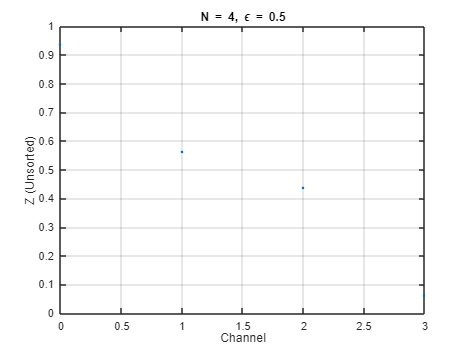

Rel. Seq. (N=4):


     0     1     2     3



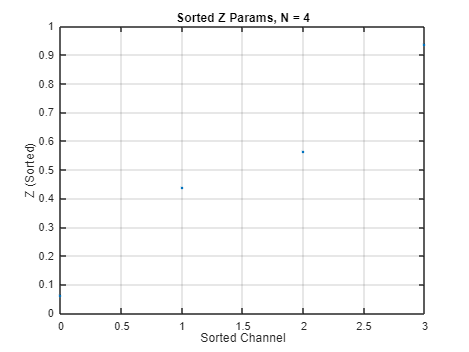

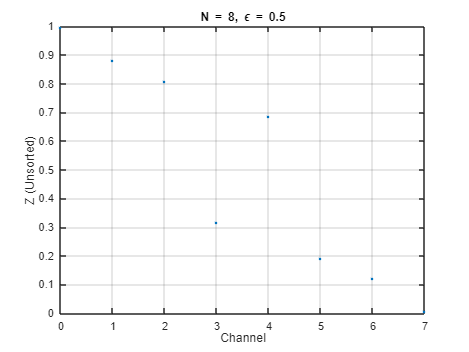

Rel. Seq. (N=8):


     0     1     2     4     3     5     6     7



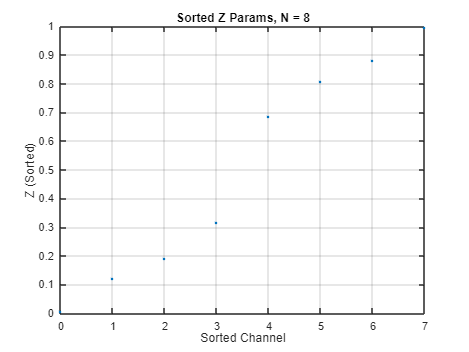

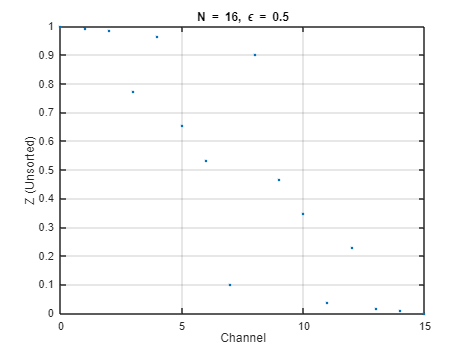

Rel. Seq. (N=16):


     0     1     2     4     8     3     5     6     9    10    12     7    11    13    14    15



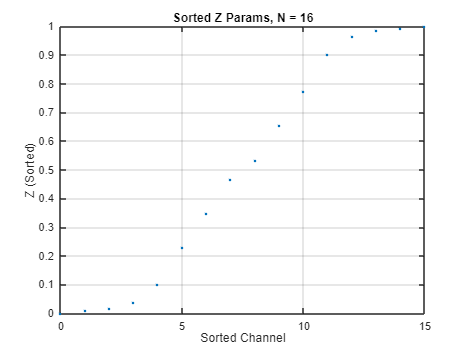

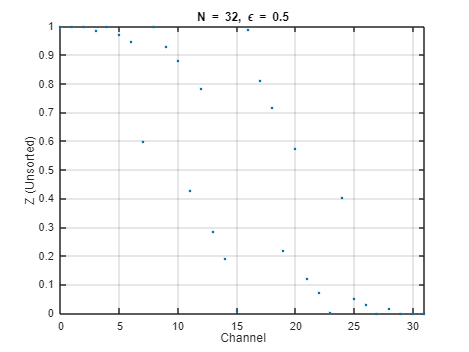

Rel. Seq. (N=32):


     0     1     2     4     8    16     3     5     6     9    10    17    12    18     7    20    11    24    13    19    14    21    22    25    26    28    15    23    27    29    30    31



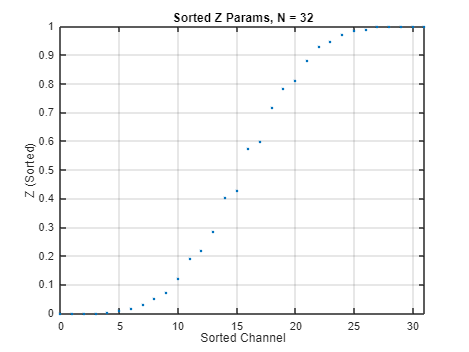

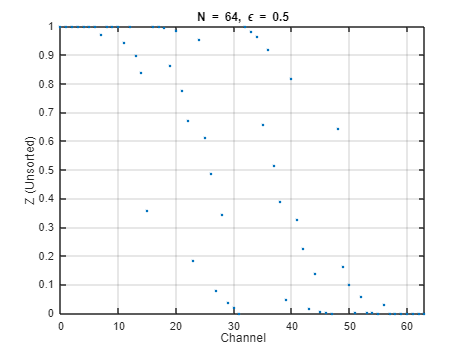

Rel. Seq. (N=64):


     0     1     2     4     8    16     3    32     5     6     9    10    12    17    18    20    33     7    34    24    11    36    13    19    14    40    21    22    35    48    25    37    26    38    15    28    41    42    23    49    44    50    27    52    39    29    56    30    43    45    46    51    53    54    57    58    31    60    47    55    59    61    62    63



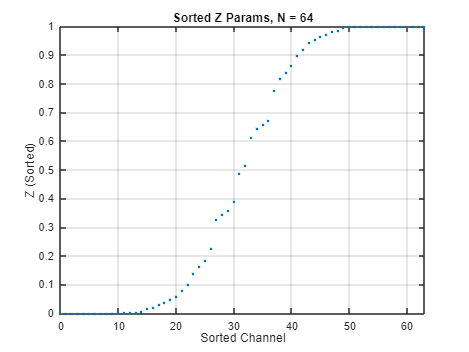

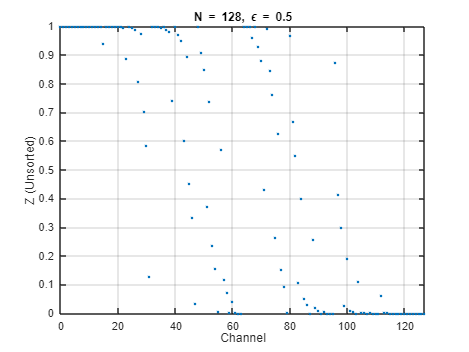

Rel. Seq. (N=128):


     0     1     2     4     8    16    32     3     5     6     9    64    10    12    17    18    20    33    24    34    36     7    65    40    11    66    13    19    14    68    21    48    22    25    35    72    26    37    38    28    41    80    67    42    15    69    49    44    23    70    96    50    73    27    74    39    52    29    81    76    43    30    56    82    45    71    97    84    51    46    98    75    88    53   100    54    77    31    57   104    83    78    58   112    85    60    47    86    99    89    90   101    55    92   102   105    79   106    59   113   108   114    61   116    87    62   120    91    93   103    94   107   109   110   115   117    63   118   121   122   124    95   111   119   123   125   126   127



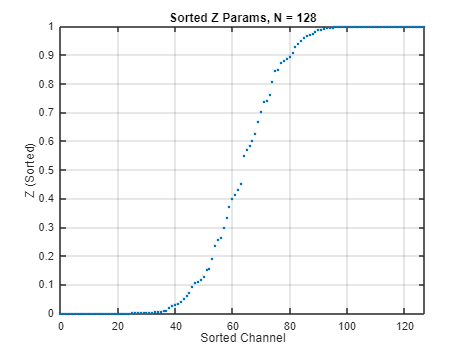

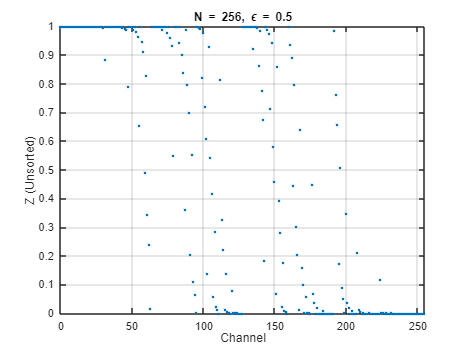

Rel. Seq. (N=256):


     0     1     2     3     4     5     6     8     9    10    12    16    17    18    32    64   128    20    24    33    34    36    40    65    66    48    68    72     7    11    13    19    14   129    21   130    80    22    25   132    35    26    37    38    28    41   136    42    96    67    44    49    69    50    70   144    73    52    74    15    76   131    81    23    56   133    82    27   160   134    39    29    84   137    43    30    97   138    45    98    51    71    88    46   145   140   192    53    75   100   146    54    77    57    83   148   161    78   104   135    58    85   162    31   139   152    86    60    99   112    89   164    47   141   193   101   147    90   142   194    55   168   102   149    92    79   105   196    59   150   176   163   106   153    87   200    61   113   165   108   154    62   114   208    91   166   143   156   195   169   103   116   224    93   170   197   120   151   177    94   107   172   198   178   201   109   1

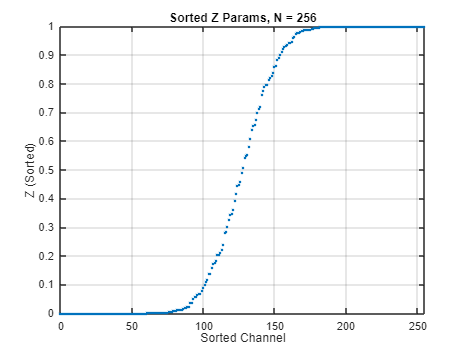

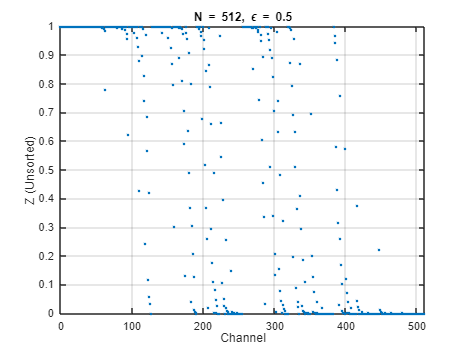

Rel. Seq. (N=512):


     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    16    17    18    19    20    21    22    24    25    26    32    33    34    35    36    37    40    48    64    65    66    68    72    80    96   128   129   130   132   136   144   256    28    38   257    41   258    42   260   160    44    49    67    50    69   264    70    52    73    74    76    56    81    82   272    84   131   133   192   134    97   137    88    98   138   100   140   145   288   146    15    23   104   148    27    39    29   259    43    30   261   161    45   152   262   162    51    46   265    71    53   112   266   164    75    54   320    77    57   268    83    78   273    58    85   168   274   193    86    60   135   194    89   276    99   139    90   101   141   196   289   147   102   142   176    92   290   280   105   149   384   106   150    31   200   292   153   263   163    47   108   113   154   267   165    55   321   114   269   166   296    

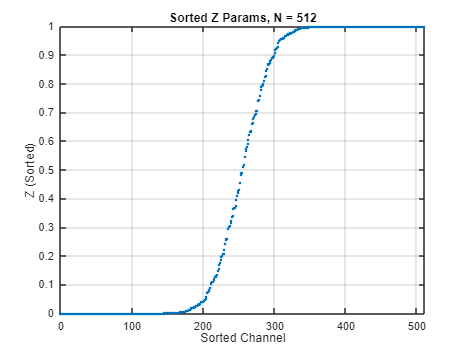

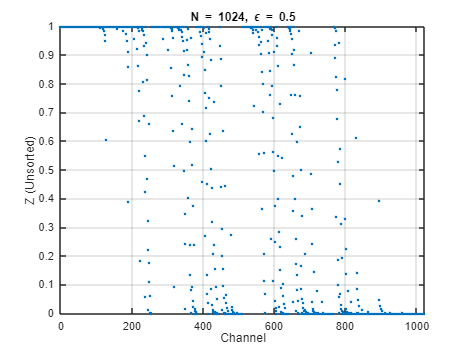

Rel. Seq. (N=1024):


           0           1           2           3           4           5           6           7           8           9          10          11          12          13          14          15          16          17          18          19          20          21          22          23          24          25          26          27          28          29          30          32          33          34          35          36          37          38          39          40          41          42          43          44          45          46          48          49          50          51          52          53          56          64          65          66          67          68          69          70          71          72          73          74          75          76          80          81          82          84          88          96          97          98         100         104         112         128         129         130         131         132         133    

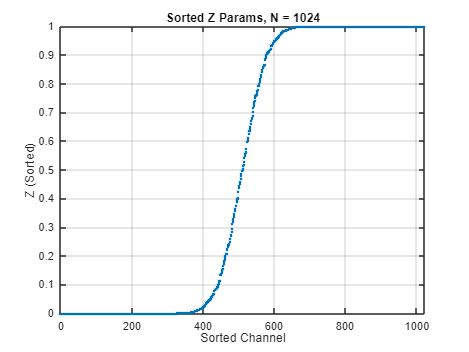

function [Z_out] = bhattacharyya_rec(N_dim, eps_val)
    Z_out = eps_val;
    levels = log2(N_dim);
    for depth = 1:levels
        updated = zeros(1, 2^depth);
        idx = 1;
        for z = Z_out
            updated(idx) = 2*z - z^2;
            updated(idx+1) = z^2;
            idx = idx + 2;
        end
        Z_out = updated;
    end
end

base_p = 0.5;
block_exponents = 2:10;

for n_exp = block_exponents
    blklen = 2^n_exp;
    Z_vals = bhattacharyya_rec(blklen, base_p);

    figure;
    plot(0:blklen-1, Z_vals, '.', 'LineWidth', 1.25);
    xlim([0 blklen-1]);
    grid on;
    xlabel('Channel');
    ylabel('Z (Unsorted)');
    title(['N = ', num2str(blklen), ', \epsilon = ', num2str(base_p)]);

    [~, rel_idx] = sort(Z_vals, 'descend');
    rel_idx = rel_idx - 1;
    disp(['Rel. Seq. (N=', num2str(blklen), '):']);
    disp(rel_idx);

    Z_sorted = sort(Z_vals);
    figure;
    plot(0:blklen-1, Z_sorted, '.', 'LineWidth', 1.25);
    xlim([0 blklen-1]);
    grid on;
    xlabel('Sorted Channel');
    ylabel('Z (Sorted)');
    title(['Sorted Z Params, N = ', num2str(blklen)]);

    drawnow;
    pause(0.1);
end